# Expand Example 3.17:

This live script is for use with the textbook

*Continuous-Time Signals and Systems: A MATLAB Integrated Approach*

by Oktay Alkin, CRC Press, 2025.

A triangular pulse signal $x(t)$ is shown in the figure.

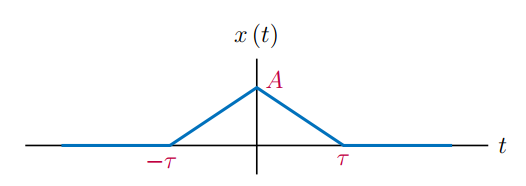

Its Fourier transform is (see Example 3.17)

        
$$X(f)=A\tau\,\textrm{sinc}^{2}(f\tau)$$


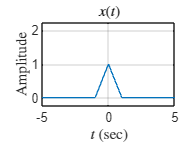

A =   1; % Peak amplitude
tau = 1; % Corner point
%
% Create a vector of time instants and compute the signal
t = [-5:0.01:5];  % Vector of time instants
x = (A+A*t/tau).*((t>=-tau)&(t<0))+(A-A*t/tau).*((t>=0)&(t<tau));
f = [-5:0.01:5];  % Vector of frequencies
% Compute the transform
tmp = sinc(f*tau);
Xf = A*tau*tmp.*tmp;
% Graph the signal
plot(t,x); grid;
axis([-5,5,-0.25,2.25]);
set(0,'defaultTextInterpreter','latex');
xlabel('$t$ (sec)');
ylabel('Amplitude');
title('$x(t)$')

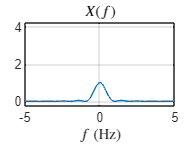

% Graph the transform
plot(f,Xf); grid;
axis([-5,5,-0.25,4.25]);
xlabel('$f$ (Hz)');
title('$X(f)$');

set(0,'defaultTextInterpreter','tex');